## Controlador clásico

clc; clear

s = tf('s');

%  1. Parámetros físicos del sistema Ball and Beam
m = 0.0027; 
R = 0.02; 
g = -9.8;
L = 0.25; 
d = 0.03;
J = 9.99e-6;

K = -m*g*d/L/(J/R^2 + m);
P_ball = K/s^2;

fprintf('Ganancia de la planta K = %.4f\n', K)

Ganancia de la planta K = 0.1147


disp('Planta del sistema:')

Planta del sistema:


P_ball


P_ball =
 
  0.1147
  ------
   s^2
 
Continuous-time transfer function.



%  2. Criterios de diseño
Mp_deseado = 0.05;   % 5%
Ts_deseado = 3;      % 3 segundos

zeta = abs(log(Mp_deseado))/sqrt(pi^2 + log(Mp_deseado)^2);
wn_min = 4/(zeta*Ts_deseado);

factor_seguridad = 1.2;
wn = factor_seguridad*wn_min;

fprintf('\n===== PARÁMETROS DE DISEÑO =====\n')


===== PARÁMETROS DE DISEÑO =====


fprintf('Zeta calculado = %.4f\n', zeta)

Zeta calculado = 0.6901


fprintf('Wn mínima = %.4f rad/s\n', wn_min)

Wn mínima = 1.9321 rad/s


fprintf('Wn seleccionada = %.4f rad/s\n', wn)

Wn seleccionada = 2.3185 rad/s



%  3. Diseño del controlador PD calculado
Kp_base = wn^2/K;
Kd_base = (2*zeta*wn)/K;

C_PD_base = pid(Kp_base, 0, Kd_base);
sys_PD_base = feedback(C_PD_base*P_ball, 1);

fprintf('\n===== CONTROLADOR PD CALCULADO =====\n')


===== CONTROLADOR PD CALCULADO =====


fprintf('Kp_base = %.4f\n', Kp_base)

Kp_base = 46.8516


fprintf('Kd_base = %.4f\n', Kd_base)

Kd_base = 27.8912



fprintf('\nPolos del sistema con PD calculado:\n')


Polos del sistema con PD calculado:


disp(pole(sys_PD_base))

  -1.6000 + 1.6779i
  -1.6000 - 1.6779i



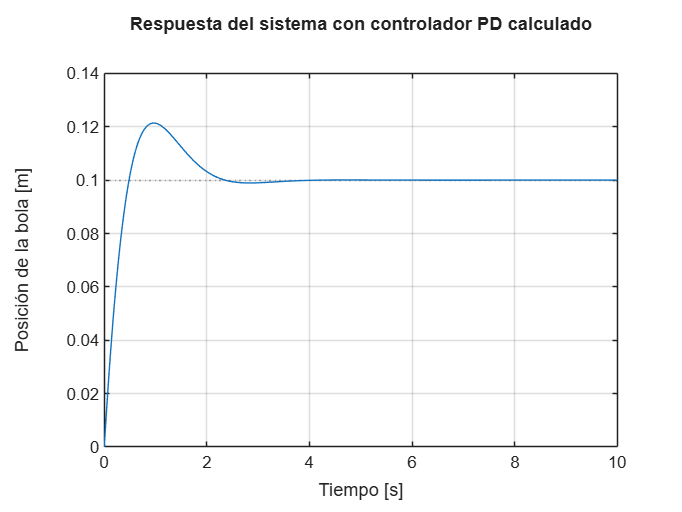


%  4. Respuesta y desempeño del PD calculado
t = 0:0.01:10;
r = 0.1;

figure;
step(r*sys_PD_base, t)
grid on;
title('Respuesta del sistema con controlador PD calculado')
xlabel('Tiempo [s]')
ylabel('Posición de la bola [m]')


info_base = stepinfo(r*sys_PD_base);

fprintf('\n===== DESEMPEÑO DEL PD CALCULADO =====\n')


===== DESEMPEÑO DEL PD CALCULADO =====


disp(info_base)

         RiseTime: 0.3682
    TransientTime: 2.0990
     SettlingTime: 2.0990
      SettlingMin: 0.0904
      SettlingMax: 0.1214
        Overshoot: 21.3587
       Undershoot: 0
             Peak: 0.1214
         PeakTime: 0.9786




%  5. Controlador PD con ajuste fino
Kp_tu = 27.45;
Kd_tu = 73.21;

C_PD_tu = pid(Kp_tu, 0, Kd_tu);
sys_PD_tu = feedback(C_PD_tu*P_ball, 1);

fprintf('\n===== CONTROLADOR PD CON AJUSTE FINO =====\n')


===== CONTROLADOR PD CON AJUSTE FINO =====


fprintf('Kp_tu = %.4f\n', Kp_tu)

Kp_tu = 27.4500


fprintf('Kd_tu = %.4f\n', Kd_tu)

Kd_tu = 73.2100



fprintf('\nPolos del sistema con PD con ajuste fino:\n')


Polos del sistema con PD con ajuste fino:


disp(pole(sys_PD_tu))

   -8.0061
   -0.3934



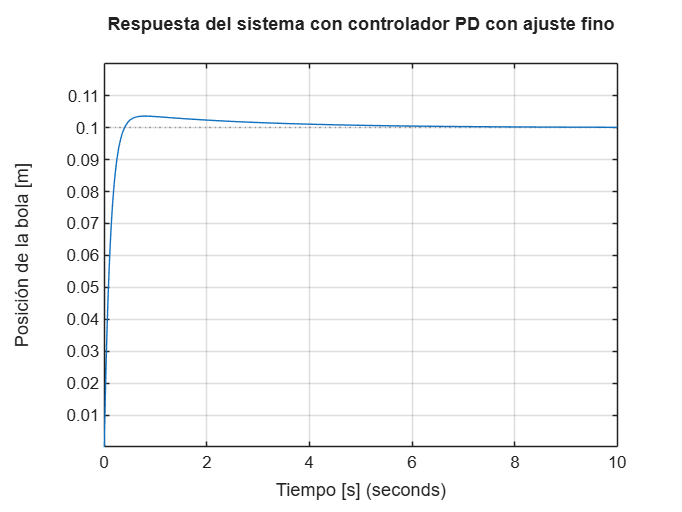


%  6. Respuesta y desempeño del PD con ajuste fino
figure;
step(r*sys_PD_tu, t)
grid on;
title('Respuesta del sistema con controlador PD con ajuste fino')
xlabel('Tiempo [s]')
ylabel('Posición de la bola [m]')


info_tu = stepinfo(r*sys_PD_tu);

fprintf('\n===== DESEMPEÑO DEL PD CON AJUSTE FINO =====\n')


===== DESEMPEÑO DEL PD CON AJUSTE FINO =====


disp(info_tu)

         RiseTime: 0.2333
    TransientTime: 2.4130
     SettlingTime: 2.4130
      SettlingMin: 0.0902
      SettlingMax: 0.1036
        Overshoot: 3.5986
       Undershoot: 0
             Peak: 0.1036
         PeakTime: 0.7938



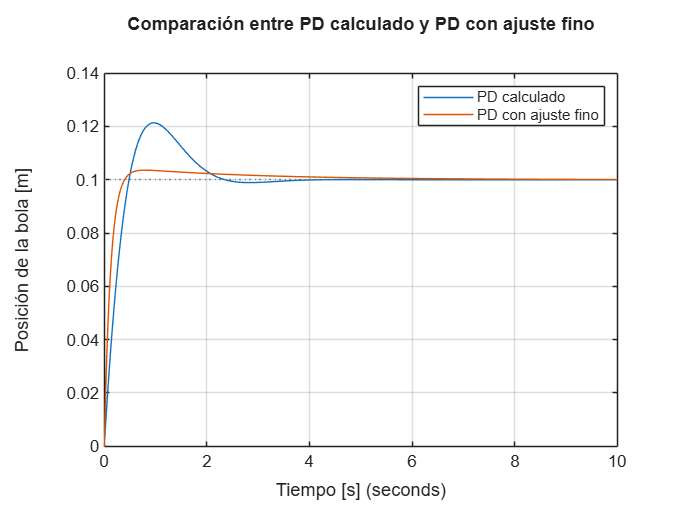


%  7. Comparación entre PD calculado y PD con ajuste fino
figure;
step(r*sys_PD_base, t)
hold on;
step(r*sys_PD_tu, t)
grid on;
legend('PD calculado', 'PD con ajuste fino')
title('Comparación entre PD calculado y PD con ajuste fino')
xlabel('Tiempo [s]')
ylabel('Posición de la bola [m]')


fprintf('\n===== COMPARACIÓN FINAL =====\n')


===== COMPARACIÓN FINAL =====


fprintf('PD calculado:     Kp = %.4f, Kd = %.4f\n', Kp_base, Kd_base)

PD calculado:     Kp = 46.8516, Kd = 27.8912


fprintf('PD ajuste fino:   Kp = %.4f, Kd = %.4f\n', Kp_tu, Kd_tu)

PD ajuste fino:   Kp = 27.4500, Kd = 73.2100



fprintf('\nTiempo de establecimiento:\n')


Tiempo de establecimiento:


fprintf('PD calculado   Ts = %.4f s\n', info_base.SettlingTime)

PD calculado   Ts = 2.0990 s


fprintf('PD ajuste fino Ts = %.4f s\n', info_tu.SettlingTime)

PD ajuste fino Ts = 2.4130 s



fprintf('\nSobreimpulso:\n')


Sobreimpulso:


fprintf('PD calculado   Mp = %.4f %%\n', info_base.Overshoot)

PD calculado   Mp = 21.3587 %


fprintf('PD ajuste fino Mp = %.4f %%\n', info_tu.Overshoot)

PD ajuste fino Mp = 3.5986 %


## Controlador en espacio de estados

clc; clear

%%  1. Parámetros físicos del sistema Ball and Beam

m = 0.0027; 
R = 0.02; 
g = -9.8;
L = 0.25; 
d = 0.03;
J = 9.99e-6;

K = -m*g*d/L/(J/R^2 + m);

fprintf('Ganancia de la planta K = %.4f\n', K)

Ganancia de la planta K = 0.1147



%%  2. Modelo en espacio de estados

A = [0 1 0 0;
     0 0 K 0;
     0 0 0 1;
     0 0 0 0];

B = [0;
     0;
     0;
     1];

C = [1 0 0 0];

D = 0;

sys_ss = ss(A,B,C,D);

disp('Modelo en espacio de estados:')

Modelo en espacio de estados:


sys_ss


sys_ss =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  0.1147       0
   x3       0       0       0       1
   x4       0       0       0       0
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



%%  3. Verificación de controlabilidad

Co = ctrb(A,B);
rango_Co = rank(Co);

fprintf('\n===== CONTROLABILIDAD DEL SISTEMA =====\n')


===== CONTROLABILIDAD DEL SISTEMA =====


fprintf('Rango de la matriz de controlabilidad = %d\n', rango_Co)

Rango de la matriz de controlabilidad = 4



if rango_Co == size(A,1)
    disp('El sistema es completamente controlable.')
else
    disp('El sistema NO es completamente controlable.')
end

El sistema es completamente controlable.



%%  4. Criterios de diseño

Mp_deseado = 0.05;   % 5%
Ts_deseado = 3;      % 3 segundos

zeta = abs(log(Mp_deseado))/sqrt(pi^2 + log(Mp_deseado)^2);
wn_min = 4/(zeta*Ts_deseado);

factor_seguridad = 1.2;
wn = factor_seguridad*wn_min;

sigma = zeta*wn;
wd = wn*sqrt(1 - zeta^2);

fprintf('\n===== PARÁMETROS DE DISEÑO =====\n')


===== PARÁMETROS DE DISEÑO =====


fprintf('Zeta calculado = %.4f\n', zeta)

Zeta calculado = 0.6901


fprintf('Wn mínima = %.4f rad/s\n', wn_min)

Wn mínima = 1.9321 rad/s


fprintf('Wn seleccionada = %.4f rad/s\n', wn)

Wn seleccionada = 2.3185 rad/s


fprintf('Sigma = %.4f\n', sigma)

Sigma = 1.6000


fprintf('Wd = %.4f\n', wd)

Wd = 1.6779



%%  5. Diseño del controlador en espacio de estados

p1 = -sigma + 1i*wd;
p2 = -sigma - 1i*wd;
p3 = -8;
p4 = -16;

polos_deseados = [p1 p2 p3 p4];

K_ss = place(A,B,polos_deseados);

A_cl = A - B*K_ss;

Nbar = -1/(C*((A - B*K_ss)\B));

sys_ss_cl = ss(A_cl, B*Nbar, C, D);

fprintf('\n===== CONTROLADOR EN ESPACIO DE ESTADOS =====\n')


===== CONTROLADOR EN ESPACIO DE ESTADOS =====


fprintf('Polos deseados:\n')

Polos deseados:


disp(polos_deseados)

  -1.6000 + 1.6779i  -1.6000 - 1.6779i  -8.0000 + 0.0000i -16.0000 + 0.0000i




fprintf('K_ss = \n')

K_ss = 


disp(K_ss)

   1.0e+03 *

    5.9970    4.6945    0.2102    0.0272




fprintf('Nbar = %.4f\n', Nbar)

Nbar = 5996.9987



fprintf('\nPolos del sistema con controlador en espacio de estados:\n')


Polos del sistema con controlador en espacio de estados:


disp(pole(sys_ss_cl))

 -16.0000 + 0.0000i
  -8.0000 + 0.0000i
  -1.6000 + 1.6779i
  -1.6000 - 1.6779i



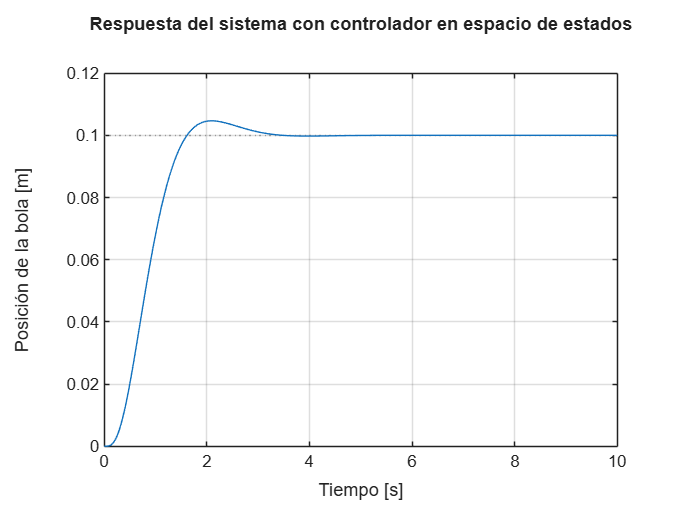


%%  6. Respuesta y desempeño del controlador en espacio de estados

t = 0:0.01:10;
r = 0.1;

figure;
step(r*sys_ss_cl, t)
grid on;
title('Respuesta del sistema con controlador en espacio de estados')
xlabel('Tiempo [s]')
ylabel('Posición de la bola [m]')


info_ss = stepinfo(r*sys_ss_cl);

fprintf('\n===== DESEMPEÑO DEL CONTROLADOR EN ESPACIO DE ESTADOS =====\n')


===== DESEMPEÑO DEL CONTROLADOR EN ESPACIO DE ESTADOS =====


disp(info_ss)

         RiseTime: 0.9583
    TransientTime: 2.7793
     SettlingTime: 2.7793
      SettlingMin: 0.0903
      SettlingMax: 0.1047
        Overshoot: 4.6779
       Undershoot: 0
             Peak: 0.1047
         PeakTime: 2.0954



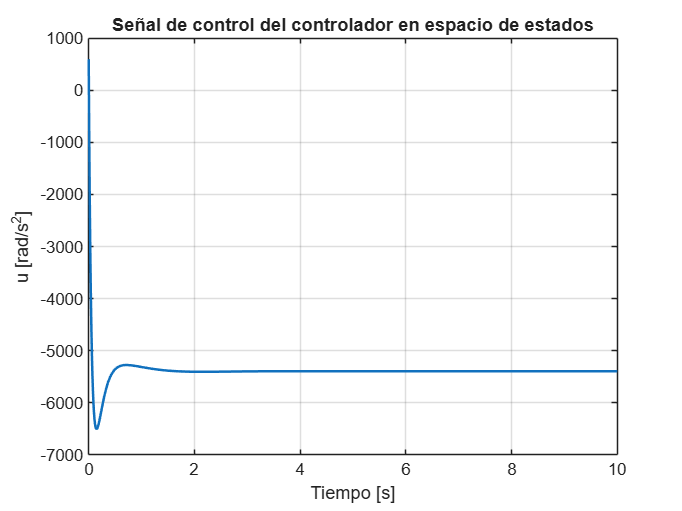


%%  7. Señal de control

[y,t,x] = step(r*sys_ss_cl,t);

u = zeros(length(t),1);

for i = 1:length(t)
    u(i) = -K_ss*x(i,:)' + Nbar*r;
end

figure;
plot(t,u,'LineWidth',1.5)
grid on;
title('Señal de control del controlador en espacio de estados')
xlabel('Tiempo [s]')
ylabel('u [rad/s^2]')


%%  8. Resumen final

fprintf('\n===== RESUMEN FINAL =====\n')


===== RESUMEN FINAL =====


fprintf('Controlador en espacio de estados por ubicación de polos\n')

Controlador en espacio de estados por ubicación de polos



fprintf('\nPolos seleccionados:\n')


Polos seleccionados:


disp(polos_deseados)

  -1.6000 + 1.6779i  -1.6000 - 1.6779i  -8.0000 + 0.0000i -16.0000 + 0.0000i




fprintf('Ganancia de realimentación de estados K_ss:\n')

Ganancia de realimentación de estados K_ss:


disp(K_ss)

   1.0e+03 *

    5.9970    4.6945    0.2102    0.0272




fprintf('Precompensador Nbar = %.4f\n', Nbar)

Precompensador Nbar = 5996.9987



fprintf('\nTiempo de establecimiento:\n')


Tiempo de establecimiento:


fprintf('Espacio de estados Ts = %.4f s\n', info_ss.SettlingTime)

Espacio de estados Ts = 2.7793 s



fprintf('\nSobreimpulso:\n')


Sobreimpulso:


fprintf('Espacio de estados Mp = %.4f %%\n', info_ss.Overshoot)

Espacio de estados Mp = 4.6779 %
